# Actividad 2

### Universidad Internacional de la Rioja

En primer lugar debemos realizar una discretización del intervalo [0,1]. Y definir la función a minimizar.

clear
n = 100;
% Hallamos un vector con las n funciones Tj(u)
function aprox = T(u,n)
for j=1:n
    t(j) = ((u(j)+u(j+1))*sqrt(1+n^2*(u(j+1)-u(j))^2))/(2*(n));
end
aprox = sum(t);

end
T(ones(1,n+1), n)

ans =    1.000000000000000


Ahora vamos a definir el gradiante


function gradiante = G(u,n)
g(1) = 1/(2*n)*(sqrt(1+n^2*(u(2)-u(1))^2) - (n^2*(u(2)-u(1))*(u(2)+u(1)))/(sqrt(1+n^2*(u(2)-u(1))^2)));
for k =2:n
    g(k)= 1/(2*n)*(sqrt(1+n^2*(u(k)-u(k-1))^2) + (n^2*(u(k)-u(k-1))*(u(k)+u(k-1)))/(sqrt(1+n^2*(u(k)-u(k-1))^2)) + ...
        sqrt(1+n^2*(u(k+1)-u(k))^2) - (n^2*(u(k+1)-u(k))*(u(k+1)+u(k)))/(sqrt(1+n^2*(u(k+1)-u(k))^2)));
end
g(n+1) = 1/(2*n)*(sqrt(1+n^2*(u(n+1)-u(n))^2) + (n^2*(u(n+1)-u(n))*(u(n+1)+u(n)))/(sqrt(1+n^2*(u(n+1)-u(n))^2)));
gradiante = g;
end

G(ones(1,n+1),n)

ans =    0.005000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000

Ahora implementamos el método del gradiante. Usaremos el método de búsqueda de Fibonacci y como valor de arranque un vector de unos.

x0 = ones(1, n-1);
tol = 10^(-6);
format long
iter = 0;
error = (G([1,x0,1],n));
error = norm(error(2:n));
while and(error > tol, iter<= 100000)
    gx = G([1,x0,1],n);
    f = @(t) T([1, x0-t*gx(2:n),1],n);
    paso = fibo(f,[0,5], 10^(-8));
    x0 = x0 - paso(1)*gx(2:n);
    iter = iter+1;
    error = (G([1,x0,1],n));
    error = norm(error(2:n));
end

Comparativa con la catenaria.

Para ello debemos primero calcular la longitud de la curva solución u(x).

function long = longitud(u,n)

for j=1:n
    l(j) = sqrt(1+n^2*(u(j+1)-u(j))^2)/n;
end
long = sum(l);
end
long = longitud([1,x0,1], n);

Ahora, la catenaria tiene la siguiente expresión. $y = y_0 + \mu*cosh\left(\frac{x-x_0}{\mu}\right)$ en dónde los parámetros $y_0,x_0 $ y $\mu$ se pueden calcular a partir de las posiciones en las que se anuda la cuerda y la longitud de la cuerda.  En concreto, los parámetros cumplen el siguiente sistema de ecuaciones.


$$ 1-y_0 =  \mu \cdot cosh\left(\frac{-x_0}{\mu}\right) \\ 1-y_0 =  \mu \cdot cosh\left(\frac{1-x_0}{\mu}\right) \\ longitud = \mu\cdot sinh\left(\frac{x_0}{\mu}\right)+\mu\cdot sinh\left(\frac{1-x_0}{\mu}\right)$$


En nuestro caso, como los dos puntos en los que se apoya la cuerda están a la misma altura, entonces $x_0 =1/2$. Por lo que la tercera ecuación es una ecuación solamente en $\mu$ cuya solución se puede aproximar con método numéricos. Vamos a aproximar el parámetro $\mu$.

f_aprox = @(mu) 2*mu*sinh(0.5/mu)-long;
b = 1;
a = eps

a =      2.220446049250313e-16


int = [a, b];
while f_aprox(a)*f_aprox(b) > 0
    b = b+1
end

while b-a > 10^(-8)
    c = (b+a)/2;
    if sign(f_aprox(c)) == sign(f_aprox(a))
        a = c;
    else
        b = c;
    end
end
mu = (a+b)/2;


Una vez estimado el parámetro $\mu$, vamos a calcular el $y_0$.

y0 = 1-mu*cosh(0.5/mu);

Ahora que ya enemos calculados los parámetros vamos a representar la comparativa de las soluciones.

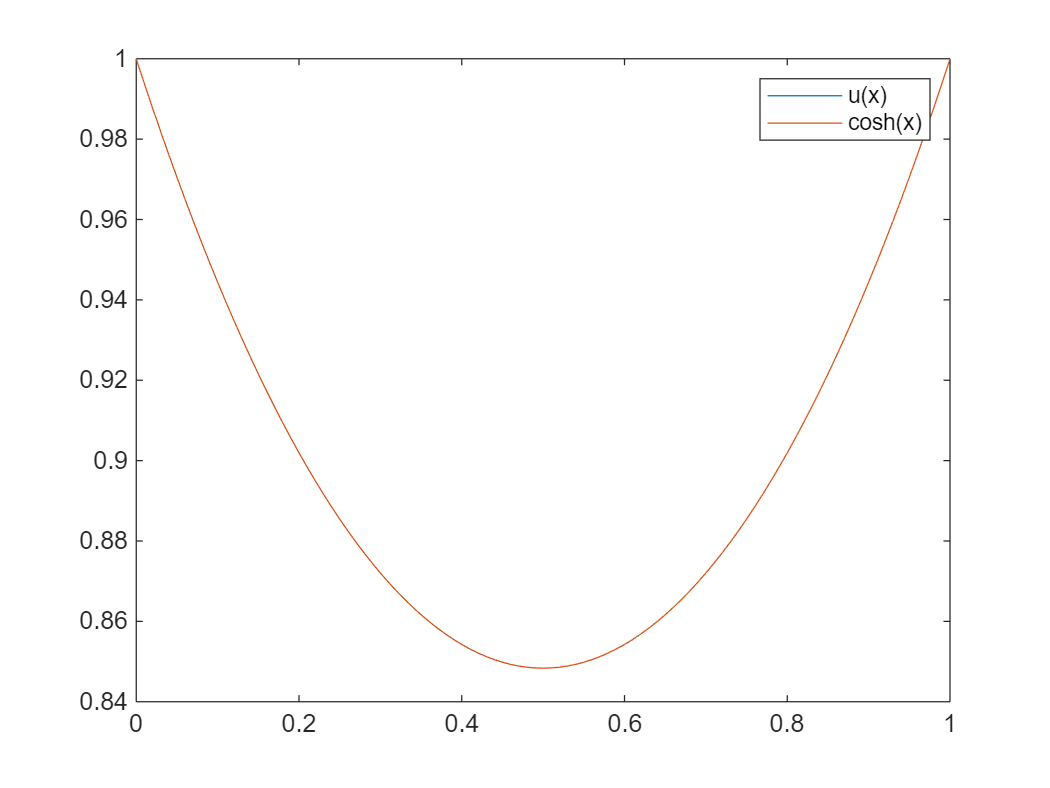


plot((0:n)/n, [1,x0,1])
hold on
plot((0:n)/n,y0 + mu*cosh((((0:n)/n)-0.5)/mu))
hold off
legend('u(x)', 'cosh(x)') 

Función de Fibonacci

function salida = fibo(f, intervalo, tol)
% Está función aplica el método de la búesqueda de fibonacci a una función
% para hayar un mínimo en un intervalo.
% f: función unimodal en el intervalo, debe introducirse como función
% anónima
% intervalo: vector de dos componentes con los extremos del intervalo.
% tol: tolerancia o error permitido, debe ser positivo
%
% Salidas: El método devuelve un vector [min, fval, iterados] 
% min: punto donde se alncanza el minimo local de la función en el intervalo
% fval: valor de la función en ese punto
% iterados: número de iteraciones utilizadas para converger.
% Calculamos los valores de la sucesión de Finonacci necesarios.
fi = [1,1];
b = intervalo(2);
a = intervalo(1);
w1 = b-a;
n = 2;
while w1 >= tol*fi(n)
    fi(n+1) = fi(n)+fi(n-1);
    n = n+1;
end
%Realizamos el primer paso a parte pues es el único con dos evaluaciones de f
% y así después solo realizar una evaluación de f en cada paso.
w1 = w1/fi(n)*fi(n-1);
xa = b - w1;
xb = a + w1;
fa = f(xa);
fb = f(xb);
k=2; % Número de pasos
while and(k<= n-2, xa < xb) %La segunda condición es para evitar errores en caso de muchas iteraciones
    w1 = w1/fi(n-k+1)*fi(n-k);  
if fa > fb % Actualizamos los valores según el valor de la función
    a = xa;
    xa = xb;
    fa = fb;
    xb = a + w1;
    fb = f(xb);
else
    b = xb;
    xb = xa;
    fb = fa;
    xa = b-w1;
    fa = f(xa);
end
k = k+1;
end
salida = [xa, fa, n-2];
end